% =========================================================
% espectrograma_comparativo.m
% Grupo G1 - Controle de Altitude de Drone
% UTFPR Apucarana - Analise de Sistemas Lineares 2026-1
% =========================================================
% Gera espectrograma comparativo do sinal de controle u(t)
% para os controladores PID e LQR.
%
% PRE-REQUISITO: ter rodado controlador_pid.m (gera dados_pid.mat)
% e receber u_lqr do Torres (vetor coluna, mesmo tamanho de t).
%
% Quando o Torres passar o u_lqr, ha duas opcoes:
%   OPCAO A — ele passa um arquivo .mat:
%       Descomentar a linha abaixo e ajustar o nome do arquivo.
%       dados_lqr = load('dados_lqr.mat');
%       u_lqr = dados_lqr.u;   % ajustar nome da variavel se necessario
%
%   OPCAO B — ele passa o script LQR completo:
%       Rodar o script dele primeiro, garantir que u_lqr esta no workspace,
%       depois rodar este script.
% =========================================================

clear; clc; close all;

%% --- Carregar dados do PID ---
if ~isfile('dados_pid.mat')
    error('Arquivo dados_pid.mat nao encontrado. Rodar controlador_pid.m primeiro.');
end
dados = load('dados_pid.mat');
t     = dados.t(:);      % vetor coluna
u_pid = dados.u(:);      % sinal de controle PID, vetor coluna

fprintf('Dados PID carregados: %d pontos, t=[%.2f, %.2f] s\n', length(t), t(1), t(end));

Dados PID carregados: 3001 pontos, t=[0.00, 30.00] s



%% --- Carregar u_lqr ---
% ---------------------------------------------------------------
% QUANDO O TORRES MANDAR OS DADOS, ESCOLHER UMA DAS OPCOES:
%
% OPCAO A: arquivo .mat do Rafael
% dados_lqr = load('dados_lqr.mat');
% u_lqr = dados_lqr.u(:);
%
% OPCAO B: vetor ja no workspace (rodar script do Rafael antes)
% u_lqr = u_lqr(:);   % garante coluna
%
% ENQUANTO NAO TEM O LQR: usa sinal simulado para testar o script.
% REMOVER o bloco abaixo quando tiver o u_lqr real.
% ---------------------------------------------------------------

if ~exist('u_lqr', 'var')
    warning('u_lqr nao encontrado no workspace. Usando sinal temporario para teste visual.');
    warning('SUBSTITUIR pelo u_lqr real do Torres antes da entrega.');
    % Sinal placeholder: resposta mais rapida e suave (simula LQR tipico)
    u_lqr = 1.5 * exp(-0.8 * t) .* cos(0.3 * t);
    u_lqr = u_lqr(:);
end


%% --- Verificar compatibilidade dos vetores ---
if length(u_lqr) ~= length(t)
    error('u_lqr tem %d pontos mas t tem %d pontos. Vetores devem ter o mesmo tamanho.', ...
        length(u_lqr), length(t));
end

%% --- Parametros do espectrograma ---
dt      = t(2) - t(1);   % passo de tempo [s]
fs      = 1 / dt;         % frequencia de amostragem [Hz]

% Parametros da janela STFT (Short-Time Fourier Transform)
% window: comprimento da janela de Hamming
% noverlap: sobreposicao entre janelas (aumentar = mais suavidade temporal)
% nfft: pontos da FFT (mais pontos = melhor resolucao em frequencia)
window  = 128;
noverlap = 64;
nfft    = 256;

fprintf('Parametros do espectrograma:\n');

Parametros do espectrograma:


fprintf('  fs = %.2f Hz (dt = %.4f s)\n', fs, dt);

  fs = 100.00 Hz (dt = 0.0100 s)


fprintf('  Janela = %d pontos (%.2f s)\n', window, window*dt);

  Janela = 128 pontos (1.28 s)


fprintf('  Sobreposicao = %d pontos (%.2f s)\n', noverlap, noverlap*dt);

  Sobreposicao = 64 pontos (0.64 s)


fprintf('  NFFT = %d\n', nfft);

  NFFT = 256


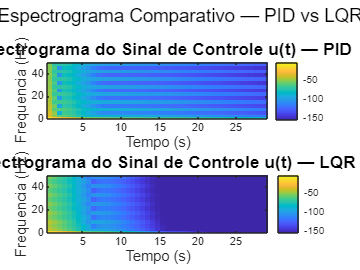


%% --- Figura: Espectrograma comparativo PID vs LQR ---
figure(1);

subplot(2,1,1);
spectrogram(u_pid, hamming(window), noverlap, nfft, fs, 'yaxis');
title('Espectrograma do Sinal de Controle u(t) — PID', 'FontSize', 13);
xlabel('Tempo (s)', 'FontSize', 11);
ylabel('Frequencia (Hz)', 'FontSize', 11);
colorbar;
clim_pid = clim;   % captura escala de cor para normalizar entre subplots

subplot(2,1,2);
spectrogram(u_lqr, hamming(window), noverlap, nfft, fs, 'yaxis');
title('Espectrograma do Sinal de Controle u(t) — LQR', 'FontSize', 13);
xlabel('Tempo (s)', 'FontSize', 11);
ylabel('Frequencia (Hz)', 'FontSize', 11);
colorbar;

% Uniformizar escala de cor entre os dois subplots para comparacao justa
subplot(2,1,1); clim(clim_pid);
subplot(2,1,2); clim(clim_pid);

sgtitle('Espectrograma Comparativo — PID vs LQR', 'FontSize', 14);

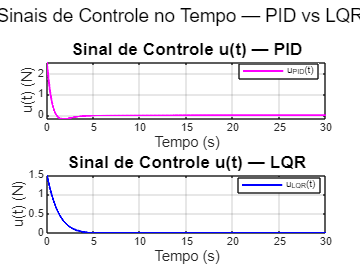


%% --- Figura 2: u(t) no tempo para referencia visual ---
figure(2);
subplot(2,1,1);
plot(t, u_pid, 'm-', 'LineWidth', 1.5);
title('Sinal de Controle u(t) — PID', 'FontSize', 13);
xlabel('Tempo (s)', 'FontSize', 11);
ylabel('u(t) (N)', 'FontSize', 11);
grid on;
legend('u_{PID}(t)', 'Location', 'best');

subplot(2,1,2);
plot(t, u_lqr, 'b-', 'LineWidth', 1.5);
title('Sinal de Controle u(t) — LQR', 'FontSize', 13);
xlabel('Tempo (s)', 'FontSize', 11);
ylabel('u(t) (N)', 'FontSize', 11);
grid on;
legend('u_{LQR}(t)', 'Location', 'best');

sgtitle('Sinais de Controle no Tempo — PID vs LQR', 'FontSize', 14);


fprintf('\n=== Script espectrograma_comparativo.m executado ===\n');


=== Script espectrograma_comparativo.m executado ===


fprintf('Salvar figuras:\n');

Salvar figuras:


fprintf('  fig_espectrograma_comparativo.png  (Figura 1) — 600 dpi\n');

  fig_espectrograma_comparativo.png  (Figura 1) — 600 dpi


fprintf('  fig_sinais_controle.png            (Figura 2) — opcional\n');

  fig_sinais_controle.png            (Figura 2) — opcional


if contains(evalc('disp(u_lqr(1))'), '') && exist('u_lqr', 'var')
    fprintf('\nATENCAO: verificar se u_lqr e o vetor real do Rafael ou o placeholder.\n');
    fprintf('Substituir antes da entrega final.\n');
end


ATENCAO: verificar se u_lqr e o vetor real do Rafael ou o placeholder.


Substituir antes da entrega final.
